% For loop
disp('List I:')

List I:


for i = 1: 3
    disp(i);
    fprintf('%c%c', 8, 8);
end

     1



     2



     3



fprintf('\n')

disp('List V:')

List V:


v = -3: 3;
for i =1: length(v)
    disp(v(i));
    fprintf('%c%c', 8, 8);
end

    -3



    -2



    -1



     0



     1



     2



     3



fprintf('\n')

disp('Sum 1 to 10:')

Sum 1 to 10:


sum = 0;
for i = 1: 10
    sum = sum + i;
end
disp(sum);

    55



disp('Sum 1 to 10 jumped by 2:')

Sum 1 to 10 jumped by 2:


sum = 0;
for i = 1: 2: 10
    sum = sum + i;
end
disp(sum);

    25



% Image processing
% Load images (imread())
img = imread('BerkeleyTower.png');
fprintf('Image size is: (height: %d, width: %d, channel: %d)\n', size(img));

Image size is: (height: 499, width: 748, channel: 3)


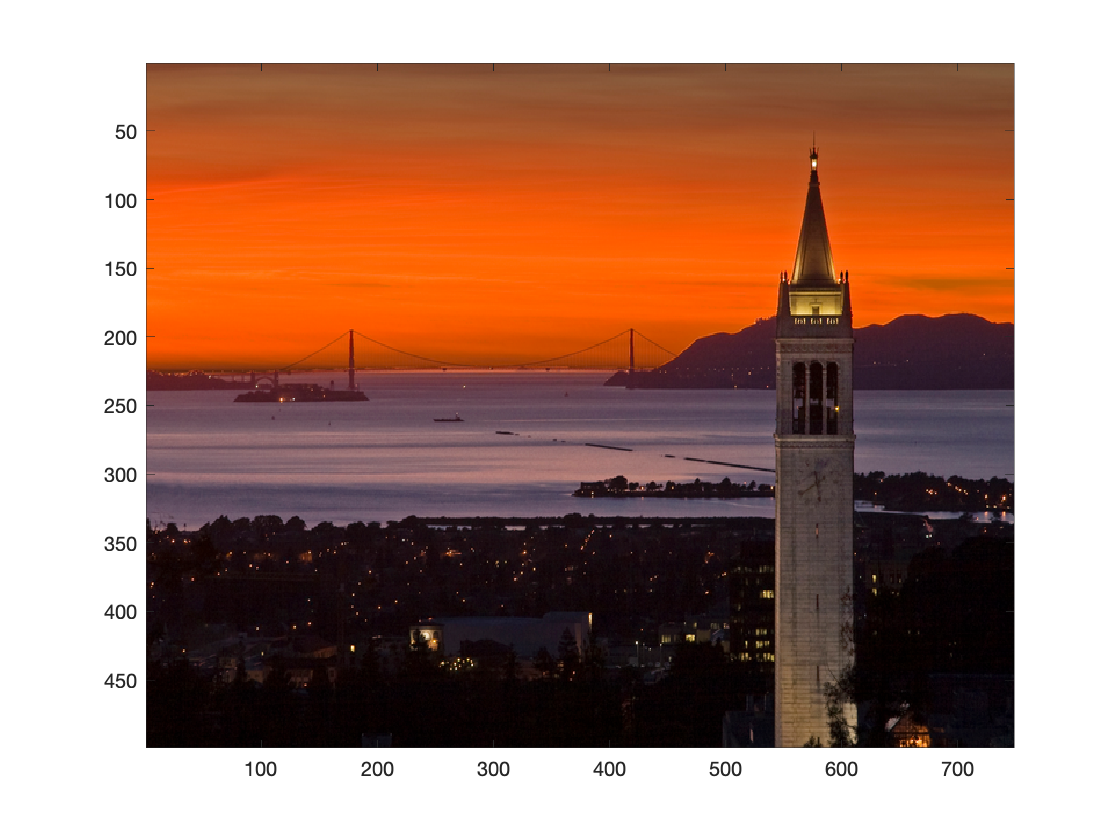

% Print images (imshow(), imagesc())
% imshow() shows an image in standard 8-bit format
% imagesc() shows an image on scaled axes with min value as white and max
% value as black
% imshow(img)
imagesc(img)

% Crop an image
img_new = img(50: 499, 530: 700, :);
% imshow(img_new);
% Save the new image to current folder (imwrite())
imwrite(img_new, './NewBerkeleyTower.png');

% RGB -> Gray (rgb2gray())
gray = rgb2gray(img);
% imshow(gray);
disp(size(gray));

   499   748



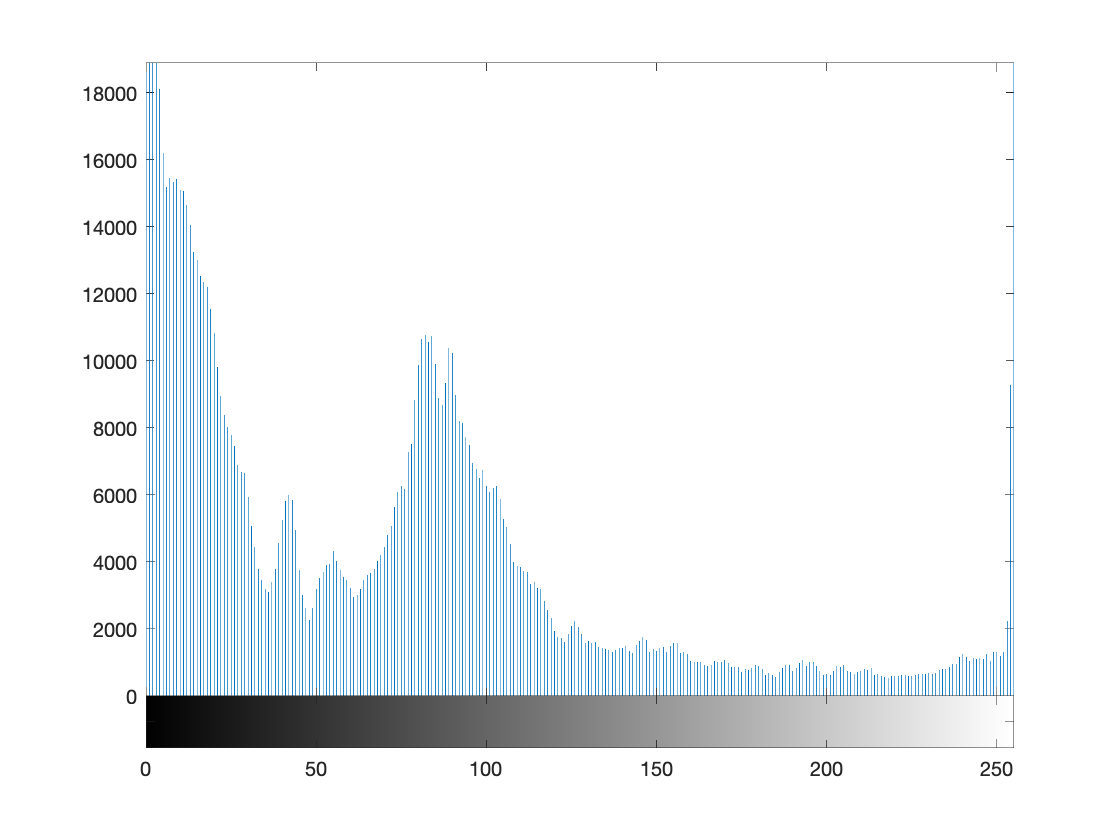

% Image data histogram
% imhist() displays a histogram with n bins for an image. n = 256 for
% default setting and n = 2 for binary images.
imhist(img);

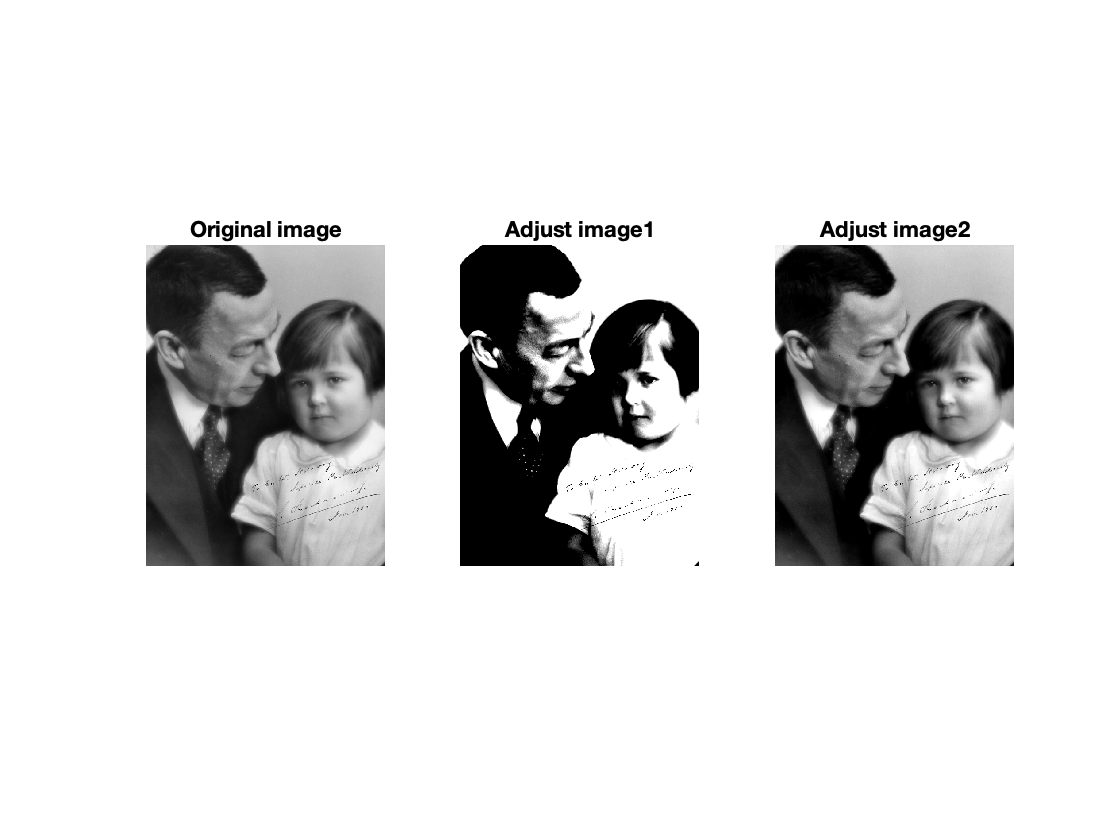

% imhist(gray);
% Adjust image intensity values. (imadjust())
% Increases the contrast of the output image
img2 = imread('Rachmaninoff.jpg');
img2 = rgb2gray(img2);

img_adj1 = imadjust(img2, [0.4, 0.6]);
img_adj2 = imadjust(img2, [0.1, 0.9]);

% Create figure for different sets of images
figure(1);

subplot(131);
imshow(img2);
title('Original image');

subplot(132);
imshow(img_adj1);
title('Adjust image1');

subplot(133);
imshow(img_adj2);
title('Adjust image2');

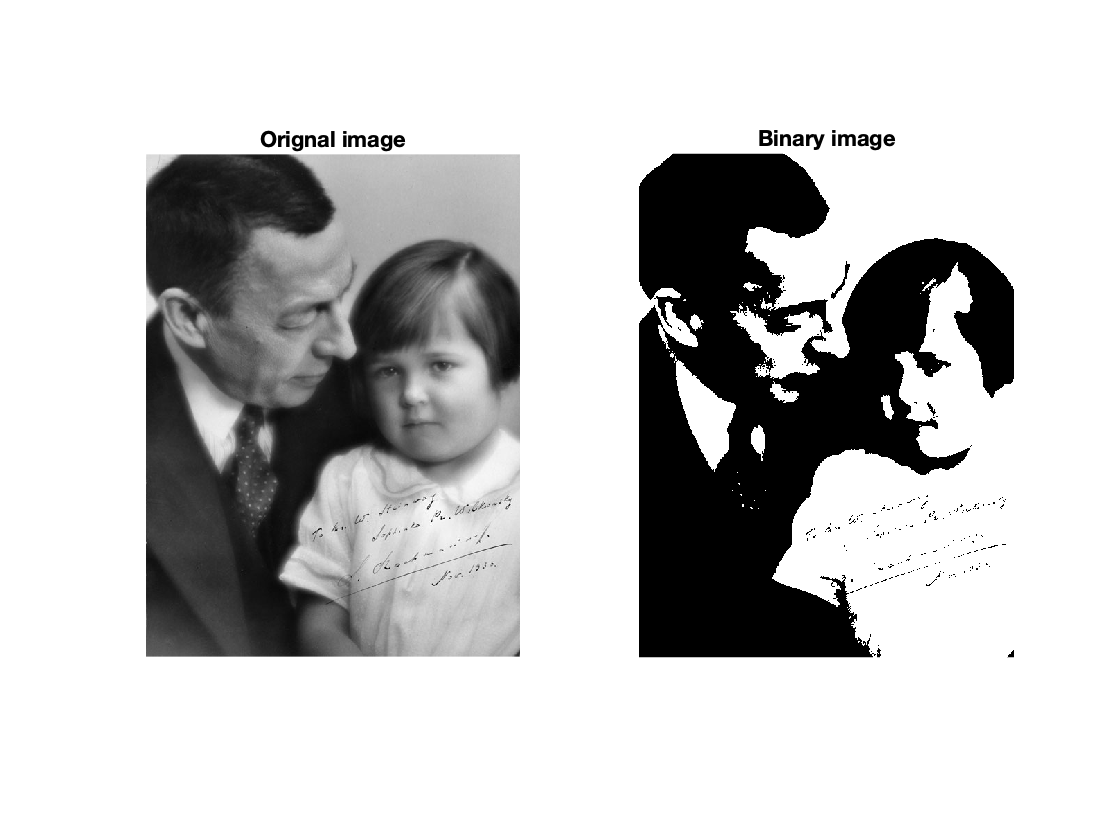

% Convert a grayscale image to a binary image
img_binary = im2bw(img2);

figure(2);

subplot(121);
imshow(img2);
title('Orignal image');

subplot(122);
imshow(img_binary);
title('Binary image');